# Analysis of installed capacity and electricity generation

Description: This algorithm calculates and plot the electricity share and nominal installed capacity share. It gives support to analyze the "decoupling" effects of renewables

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 10/2020

clc
clear
close all

## Load Data

load Data_EIA.mat

## Variables

% Electricity Capacity 

% Electricity installed capacity (million kW)
El_Cap_Tot=Data_EIA.El_Cap_Tot;%[GW]
% nuclear electricity installed capacity (million kW)
El_Cap_Nuc=Data_EIA.El_Cap_Nuc;%[GW]
% fossil fuels electricity installed capacity (million kW)
El_Cap_Fos=Data_EIA.El_Cap_Fos;%[GW]
% renewable electricity installed capacity (million kW)
El_Cap_Ren=Data_EIA.El_Cap_Ren;%[GW]
% hydroelectricity installed capacity (million kW)
El_Cap_Hyd=Data_EIA.El_Cap_Hyd;%[GW]
% geothermal electricity installed capacity (million kW)
El_Cap_Geo=Data_EIA.El_Cap_Geo;%[GW]
% solar electricity installed capacity (million kW)
El_Cap_Sol=Data_EIA.El_Cap_Sol;%[GW]
% wind electricity installed capacity (million kW)
El_Cap_Win=Data_EIA.El_Cap_Win;%[GW]
% biomass and waste electricity installed capacity (million kW)
El_Cap_Bio=Data_EIA.El_Cap_Bio;%[GW]

% Electricity Generation
% electricity net generation (billion kWh)
El_Gen_Tot=Data_EIA.El_Gen_Tot;%[TWh]
% nuclear electricity net generation (billion kWh)
El_Gen_Nuc=Data_EIA.El_Gen_Nuc;%[TWh]
% fossil fuels electricity net generation (billion kWh)
El_Gen_Fos=Data_EIA.El_Gen_Fos;%[TWh
% renewable electricity net generation (billion kWh)
El_Gen_Ren=Data_EIA.El_Gen_Ren;%[TWh]
% hydroelectricity net generation (billion kWh)
El_Gen_Hyd=Data_EIA.El_Gen_Hyd;%[TWh]
% geothermal electricity net generation (billion kWh)
El_Gen_Geo=Data_EIA.El_Gen_Geo;%[TWh]
% solar, tide, wave, fuel cell electricity net generation (billion kWh)
El_Gen_Sol=Data_EIA.El_Gen_Sol;%[TWh]
% wind electricity net generation (billion kWh)
El_Gen_Win=Data_EIA.El_Gen_Win;%[TWh]
% biomass and waste electricity net generation (billion kWh)
El_Gen_Bio=Data_EIA.El_Gen_Bio;%[TWh]

Year=1980:2017;

%% Colormap

% Color=[202,0,32    % Biomass
%        0,104,55    % Geothermal
%        44,123,182  % Hydro
%        244,165,130 % Solar
%        150,150,150]/255;% Wind
Color=[85,200,60       % Biomass 0,104,55  
      202,0,32          % Geothermal
      33,102,172        % Hydro
      255,199,44      % Solar 244,109,67 
      146,197,222]/255; % Wind 



## Electricity Generation

F_El_Gen_Fos=El_Gen_Fos(1,:)./El_Gen_Tot(1,:);
F_El_Gen_Nuc=El_Gen_Nuc(1,:)./El_Gen_Tot(1,:);
F_El_Gen_Ren=El_Gen_Ren(1,:)./El_Gen_Tot(1,:);

## Fraction Capacity installed

F_Cap_Fos=El_Cap_Fos(1,:)./El_Cap_Tot(1,:);
F_Cap_Nuc=El_Cap_Nuc(1,:)./El_Cap_Tot(1,:);
F_Cap_Ren=El_Cap_Ren(1,:)./El_Cap_Tot(1,:);

F_Gen_Bio=El_Gen_Bio(1,:)./El_Gen_Ren(1,:);
F_Gen_Geo=El_Gen_Geo(1,:)./El_Gen_Ren(1,:);
F_Gen_Hyd=El_Gen_Hyd(1,:)./El_Gen_Ren(1,:);
F_Gen_Sol=El_Gen_Sol(1,:)./El_Gen_Ren(1,:);
F_Gen_Win=El_Gen_Win(1,:)./El_Gen_Ren(1,:);


## Installed capacity and electricity generation

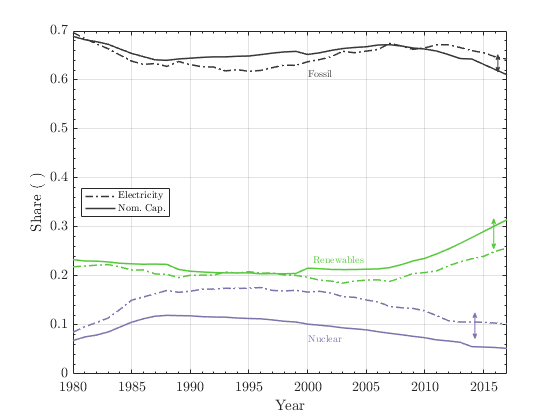

 
figure('Name','Capacity and Electricity Generated Arrows')
plot(Year,F_El_Gen_Fos,'-.','Color',[55 55 55]/255,'linewidth',1.5)
hold on
plot(Year,F_Cap_Fos,'Color',[55 55 55]/255,'linewidth',1.5)
plot(Year,F_El_Gen_Nuc,'-.','Color',[128,115,172]/255,'linewidth',1.5)
plot(Year,F_Cap_Nuc,'Color',[128,115,172]/255,'linewidth',1.5)
plot(Year,F_El_Gen_Ren,'-.','Color',Color(1,:),'linewidth',1.5)
plot(Year,F_Cap_Ren,'Color',Color(1,:),'linewidth',1.5)
xlim([1980 2017])
% Arrows
annotation('doublearrow',[0.889 0.889],[0.8285 0.8697],'Color',[.25 .25 .25],'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)
annotation('doublearrow',[0.848 0.848],[0.1739 0.2351]+0.02,'Color',[128,115,172]/255,'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)
annotation('doublearrow',[0.8816 0.8816],[0.4079 0.479],'Color',Color(1,:),'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)

%text
text(2000,0.61,'Fossil','Interpreter','latex','Color',[.25 .25 .25])
text(2000.5,0.23,'Renewables','Interpreter','latex','Color',Color(1,:))
text(2000,0.07,'Nuclear','Interpreter','latex','Color',[128,115,172]/255)
leg={'$$\mathrm{Electricity}$$';'$$\mathrm{Nom.~Cap.}$$'};
legend(leg,'location','west','FontSize', 10,'NumColumns',1,'interpreter','latex')

xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Share~(~)}$$','interpreter','latex')

box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Share_El_Cap.eps');
print('-dpng','-r400','Share_El_Cap.png');

## Figure and subfigure

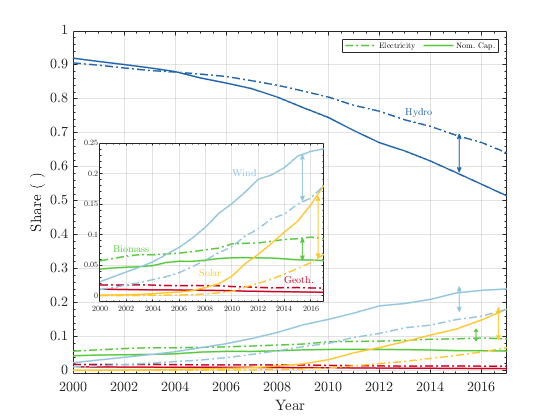

figure('Name','Subfigure Arrows')
plot(Year,F_Gen_Bio,'-.','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,El_Cap_Bio(1,:)./El_Cap_Ren(1,:),'Color',Color(1,:),'linewidth',1.5)
plot(Year,F_Gen_Geo,'-.','Color',Color(2,:),'linewidth',1.5)
plot(Year,El_Cap_Geo(1,:)./El_Cap_Ren(1,:),'Color',Color(2,:),'linewidth',1.5)
plot(Year,F_Gen_Hyd,'-.','Color',Color(3,:),'linewidth',1.5)
plot(Year,El_Cap_Hyd(1,:)./El_Cap_Ren(1,:),'Color',Color(3,:),'linewidth',1.5)
plot(Year,F_Gen_Sol,'-.','Color',Color(4,:),'linewidth',1.5)
plot(Year,El_Cap_Sol(1,:)./El_Cap_Ren(1,:),'Color',Color(4,:),'linewidth',1.5)
plot(Year,F_Gen_Win,'-.','Color',Color(5,:),'linewidth',1.5)
plot(Year,El_Cap_Win(1,:)./El_Cap_Ren(1,:),'Color',Color(5,:),'linewidth',1.5)

leg={'$$\mathrm{Bio.~El.}$$';'$$\mathrm{Bio.~Cap.}$$'; ...
    '$$\mathrm{Geo.~El.}$$';'$$\mathrm{Geo.~Cap.}$$'; ...
    '$$\mathrm{Hyd.~El.}$$';'$$\mathrm{Hyd.~Cap.}$$'; ...
    '$$\mathrm{Sol.~El.}$$';'$$\mathrm{Sol.~Cap.}$$';...
    '$$\mathrm{Wind~El.}$$';'$$\mathrm{Wind~Cap.}$$';};
legend({'Electricity','Nom. Cap.'},'Location','northeast','FontSize', 8,'NumColumns',5,'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Share~(~)}$$','interpreter','latex')
ylim([-0.01 1])
xlim([2000 2017])
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% Text
text(2013,0.76,'Hydro','Interpreter','latex','Color',Color(3,:))

% Small figure inside
% Size
axes('Position',[.178 .26+0.02 .4 .38])

plot(Year,F_Gen_Bio,'-.','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,El_Cap_Bio(1,:)./El_Cap_Ren(1,:),'Color',Color(1,:),'linewidth',1.5)
plot(Year,F_Gen_Geo,'-.','Color',Color(2,:),'linewidth',1.5)
plot(Year,El_Cap_Geo(1,:)./El_Cap_Ren(1,:),'Color',Color(2,:),'linewidth',1.5)
plot(Year,F_Gen_Sol,'-.','Color',Color(4,:),'linewidth',1.5)
plot(Year,El_Cap_Sol(1,:)./El_Cap_Ren(1,:),'Color',Color(4,:),'linewidth',1.5)
plot(Year,F_Gen_Win,'-.','Color',Color(5,:),'linewidth',1.5)
plot(Year,El_Cap_Win(1,:)./El_Cap_Ren(1,:),'Color',Color(5,:),'linewidth',1.5)

hold on

ylim([-0.01 0.25])
xlim([2000 2017])
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',8,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% Big arrow
annotation('doublearrow',[0.82 0.82],[0.22 0.28]+0.038,'Color',Color(5,:),'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)
annotation('doublearrow',[0.89 0.89],[0.152 0.23]+0.038,'Color',Color(4,:),'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)
annotation('doublearrow',[0.82 0.82],[0.522 0.613]+0.068,'Color',Color(3,:),'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)
annotation('doublearrow',[0.85 0.85],[0.179 0.15]+0.038,'Color',Color(1,:),'Head1Width',5,'Head2Width',5,'Head1Length',3,'Head2Length',3)
% Small arrow
annotation('doublearrow',[0.54 0.54],[0.502 0.612]+0.02,'Color',Color(5,:),'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)
annotation('doublearrow',[0.568 0.568],[0.365 0.513]+0.02,'Color',Color(4,:),'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)
annotation('doublearrow',[0.54 0.54],[0.360 0.414]+0.02,'Color',Color(1,:),'Head1Width',5,'Head2Width',5,'Head1Length',5,'Head2Length',5)
text(2001,0.075,'Biomass','Interpreter','latex','Color',Color(1,:))
text(2014,0.025,'Geoth.','Interpreter','latex','Color',Color(2,:))
text(2007.5,0.035,'Solar','Interpreter','latex','Color',Color(4,:))
text(2010,0.2,'Wind','Interpreter','latex','Color',Color(5,:))
print('-dpng','-r400','Ren_Share_El_cap.png');